# **Distributed-parameter transducer model**

# **for the stepped amplitude transformer**

**2023-01-03 ~ **

# **D-constant**

**2023-07-18 ~ **

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

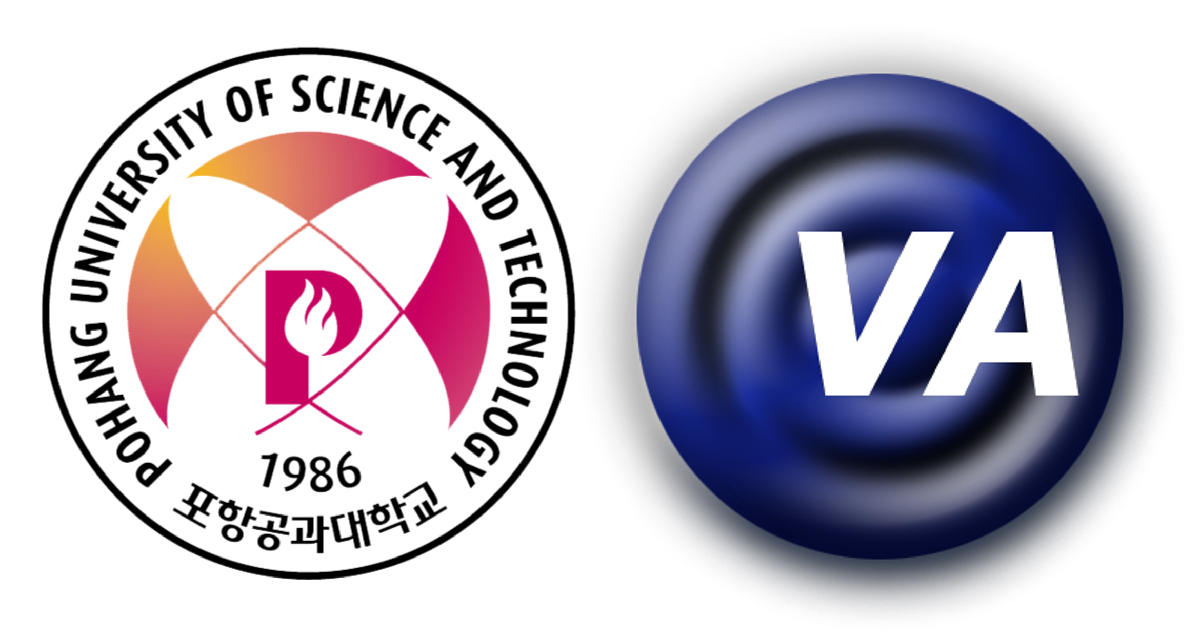

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear

% Define the simulation frequency
% f = 75e3;   % 75 [kHz]
syms f

% Load the material properties
mat = import_material('materials_OBS_loss_D.txt');
mat.Y33D('C-21') = mat.Y33('C-21')/(1-mat.k33('C-21')^2);
mat.v3D('C-21') = sqrt(mat.Y33D('C-21')/mat.rho('C-21'));

% Define the structure
n_start = 2;    % Start index of node;
n_end   = 3;    % End index of node;
if n_start > n_end
    disp("Error: the end index of node must be greater than start index!");
    return
end
e_no    = n_end - n_start;
n_no    = e_no+1;
S = sprintf("The number of elements:    %d\n" + ...
    "The number of nodes:       %d",e_no,n_no);
disp(S);

The number of elements:    1
The number of nodes:       2


e_piezo = 2;  % Index of piezoelectric bar

% Initialize the symbols for material properties and design parameters of elements

% Mechanical
rho = sym('rho_%d', [1 n_end]); % Density
E   = sym('E_%d',   [1 n_end]); % Young's modulus
nu  = sym('nu_%d',  [1 n_end]); % Poisson ratio
c   = sym('c_%d',   [1 n_end]); % Longitudinal wave speed
k   = sym('k_%d',   [1 n_end]); % Longitudinal wave number
l   = sym('l_%d',   [1 n_end]); % Length of element
A   = sym('A_%d',   [1 n_end]); % Area of element

Z   = sym('Z_%d',   [1 n_end]); % Acoustical impedance

% Electircal
eps_33  = sym('eps_33');        % Dielectric constant, eps_33
eps_0   = sym('eps_0');         % Vaccum permitivity, eps_0
N_piezo = sym('N_piezo');       % Number of Piezo

% Mechanical-electrical
d_33    = sym('d_33');          % Piezoelectric charge constant, d_33
g_33    = sym('g_33');          % Piezoelectric voltage constant, g_33
k_33    = sym('k_33');          % Electromechanical coupling, k_33


The effort and flow variable vectors are $\mathbf{F}=
\left[
\matrix{
F_1\cr
F_2\cr
F_3\cr
\vdots \cr
F_{-2}\cr
F_{-1}\cr
F_0\cr
}
\right]$ and $\mathbf{u}=
\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
\vdots \cr
u_{-2}\cr
u_{-1}\cr
u_0\cr
}
\right]$ where 1 and 0 are the node's start and end indices, and the minus sign is the reversed order from the end index.

% Initialize the symbols for effort and flow variable vectors
F   = sym('F_%d',[1 n_end+1]).';
V   = sym('V');
F   = subs(F,F(4),V);
u   = sym('u_%d',[1 n_end+1]).';
I   = sym('I');
u   = subs(u,u(4),I);

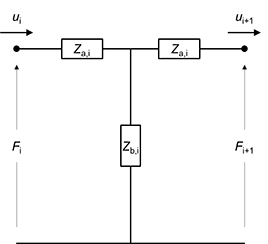

**Figure 1** The symmetric T-network circuit representation of a bar where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

By the KCL,


$$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}}\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}}
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1}
}
\right]

=

\left[
\matrix{
F_{i}\cr
-F_{i+1}\cr
}
\right]$$


% Calculating the bar's impedance for symmetric T-network
Z_b = sym('Z_b_%d',[1 n_end]);  % Z_b
Z_c = sym('Z_c_%d',[1 n_end]);  % Z_c = Z_a + Z_b
Z_d = sym('Z_d_%d',[1 n_end]);  % Z_d for the boundary conditions of both ends

for i=n_start:n_end
    Z_b(i) = -1j*rho(i)*c(i)*A(i)/(sin(k(i)*l(i)));
    Z_c(i) = -1j*rho(i)*c(i)*A(i)*cot(k(i)*l(i));
end

% Z(i) = rho(i)*c(i)*A(i)
% for i=n_start:n_end
%     Z_b(i) = -1j*Z(i)/(sin(k(i)*l(i)));
%     Z_c(i) = -1j*Z(i)*cot(k(i)*l(i));
% end

% rho(1:n_start-1)    = [];
% c(1:n_start-1)      = [];
% k(1:n_start-1)      = [];
% l(1:n_start-1)      = [];
% A(1:n_start-1)      = [];


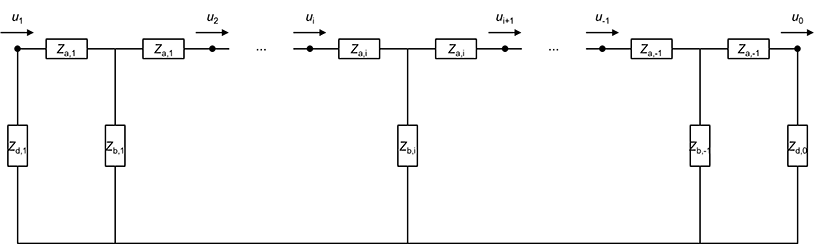

**Figure 2** The symmetric T-network circuit representation of bars mechanically connected in series and its boundary conditions of both ends

When bars are mechanically connected in series and there are the arbitrary impedances, $Z_{\rm{d}}$, at both ends without external force, $\mathbf{F}=\mathbf{Z} \cdot \mathbf{u}=[0]$.

And the impedance matrix is $Z=
\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & \cdots & 0 & 0 & 0 \cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} &  \cdots & 0 & 0 & 0 \cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & \cdots & 0 & 0 & 0 \cr
\vdots & \vdots & \vdots & \ddots & \vdots & \vdots & \vdots \cr
0 & 0 & 0 & \cdots & Z_{\rm{c,-3}}+Z_{\rm{c,-2}} & -Z_{\rm{b,-2}} & 0 \cr
0 & 0 & 0 & \cdots & -Z_{\rm{b,-2}} & Z_{\rm{c,-2}}+Z_{\rm{c,-1}} & -Z_{\rm{b,-1}} \cr
0 & 0 & 0 & \cdots & 0 & -Z_{\rm{b,-1}} & Z_{\rm{c,-1}}+Z_{\rm{d,0}} \cr
}
\right]$ where $Z_{\rm{a,i}}=j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \tan{\left({\frac{k_{\rm{i}} l_{\rm{i}}}{2}}\right)}$, $Z_{\rm{b,i}}=-\frac{j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}}}{\sin{\left(k_{\rm{i}} l_{\rm{i}}\right)}}$, $Z_{\rm{c,i}}=Z_{\rm{a,i}}+Z_{\rm{b,i}}=-j\rho_{\rm{i}} c_{\rm{i}} A_{\rm{i}} \cot{\left(k_{\rm{i}} l_{\rm{i}}\right)}$.

% Constructing the impedance matrix
Z = sym('Z_%d_%d',[n_end+1 n_end+1]);

Z(n_start,n_start)          = Z_c(n_start) + Z_d(n_start);
Z(n_start,n_start+1)        = -Z_b(n_start);
Z(n_start,n_start+2:n_end)  = 0;

for i=n_start+1:n_end-1
    Z(i,n_start:i-2)  = 0;
    Z(i,i-1)    = -Z_b(i-1);
    Z(i,i)      = sum(Z_c(i-1:i));
    Z(i,i+1)    = -Z_b(i);
    Z(i,i+2:n_end)= 0;
end

Z(n_end, n_start:n_end-2) = 0;
Z(n_end, n_end-1)   = -Z_b(n_end-1);
Z(n_end, n_end)     = Z_c(n_end-1) + Z_d(n_end);

Z

$$Z = \left(\begin{array}{cccc} Z_{1,1} & Z_{1,2} & Z_{1,3} & Z_{1,4}\\ Z_{2,1} & Z_{d,2}-A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i} & \frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)} & Z_{2,4}\\ Z_{3,1} & \frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)} & Z_{d,3}-A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i} & Z_{3,4}\\ Z_{4,1} & Z_{4,2} & Z_{4,3} & Z_{4,4} \end{array}\right)$$

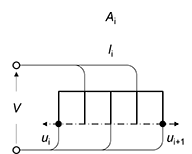

**Figure 3** 4 Piezoelectric bars mechanically connected in series and electrically in parallel

아래 그림 바꿔야 함.

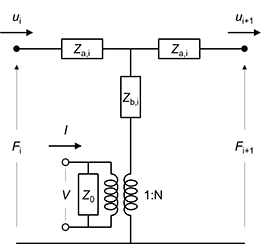

**Figure 4** The symmetric T-network circuit representation of piezoelectric bars mechanically connected in series and electrically in parallel

By KCL,

$\left[
\matrix{
Z_{\rm{c,i}} & -Z_{\rm{b,i}} & NZ_0\cr
-Z_{\rm{b,i}} & Z_{\rm{c,i}} & -NZ_0\cr
NZ_0 & -NZ_0 & Z_0
}
\right]

\left[
\matrix{
u_{i} \cr
u_{i+1} \cr
I
}
\right]

=

\left[
\matrix{
F_{i}\cr
-F_{i+1}\cr
V
}
\right]$where $Z_0=\frac{1}{j \omega C_0}$, $C_0=\varepsilon_{33}^{T}\frac{A_i}{l_i} \left( 1-k_{33}^2 \right)$, $N=\frac{A_{i} \thinspace d_{33}}{l_{i} \thinspace s_{33}^{E}}
=\frac{A_{i} \thinspace g_{33}}{l_{i} \thinspace s_{33}^{E} \thinspace \beta_{33}^{T}}
=\frac{A_{i} \thinspace \varepsilon_{33}^{T} \thinspace g_{33} \left(1-k_{33}^2 \right)}{l_{i} \thinspace s_{33}^{D}}
=C_0\frac{g_{33}}{s_{33}^{D}}$

C0 = N_piezo^2*eps_0*eps_33*A(e_piezo)/l(e_piezo)*(1-k_33^2);
Z0 = 1/(1j*2*pi*f*C0);
% N = A(e_piezo)/l(e_piezo)*g_33*E(e_piezo)*(1-k_33^2)*eps_0*eps_33;
N = C0*g_33*E(e_piezo)/N_piezo;

% syms N Z0

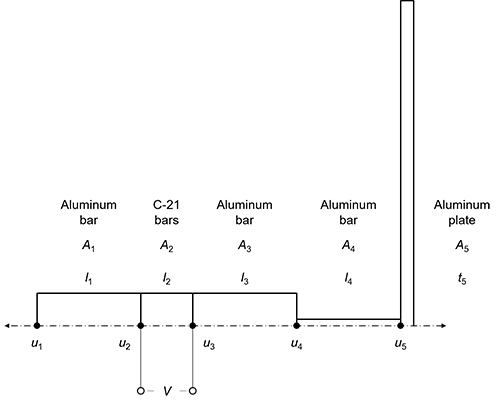

**Figure 5** Typical stepped-plate transducer

아래 그림 바꿔야 함.

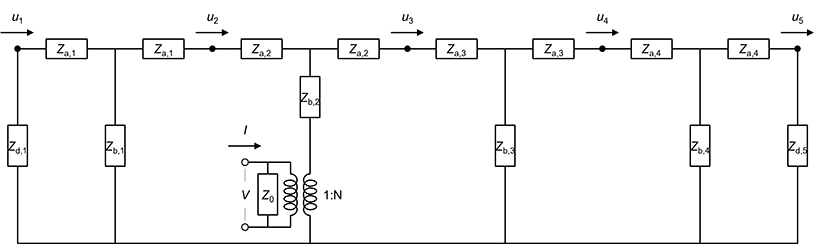

**Figure 6 **The distributed network representation of typical stepped-plate transudcer

By KCL,


$$\left[
\matrix{
Z_{\rm{c,1}}+Z_{\rm{d,1}}  & -Z_{\rm{b,1}} & 0 & 0 & 0 & 0\cr
-Z_{\rm{b,1}} & Z_{\rm{c,1}}+Z_{\rm{c,2}} & -Z_{\rm{b,2}} & 0 & 0 & NZ_0\cr
0 & -Z_{\rm{b,2}} & Z_{\rm{c,2}}+Z_{\rm{c,3}} & -Z_{\rm{b,3}} & 0 & -NZ_0\cr
0 & 0 & -Z_{\rm{b,3}} & Z_{\rm{c,3}}+Z_{\rm{c,4}} & -Z_{\rm{b,4}} & 0\cr
0 & 0 & 0 & -Z_{\rm{b,4}} & Z_{\rm{c,4}}+Z_{\rm{d,5}} & 0\cr
0 & NZ_0 & -NZ_0 & 0 & 0 & Z_0
}
\right]

\left[
\matrix{
u_1\cr
u_2\cr
u_3\cr
u_4\cr
u_5\cr
I
}
\right]

=

\left[
\matrix{
0\cr
0\cr
0\cr
0\cr
0\cr
V
}
\right]$$


Z(n_end+1,1:n_end+1)    = 0;
Z(n_end+1,e_piezo)      = N*Z0;
Z(n_end+1,e_piezo+1)    = -N*Z0;

Z(1:n_end+1,n_end+1)    = 0;
Z(e_piezo,n_end+1)      = N*Z0;
Z(e_piezo+1,n_end+1)    = -N*Z0;

Z(n_end+1,n_end+1)      = Z0;

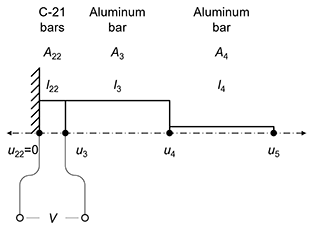

**Figure 7** The aluminum stepped amplitude transformer driven by two piezoelectric bars, C-21, fixed on one end and free on the other end

아래 그림 바꿔야 함.

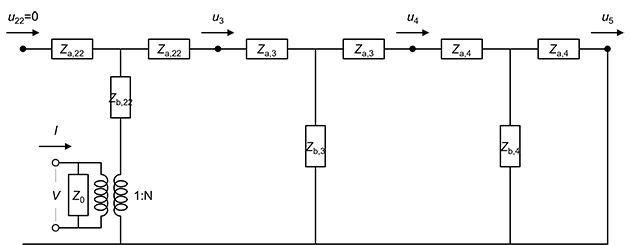

**Figure 8** The distributed network representation of the aluminum stepped amplitude transformer driven by piezoelectric bars

% For the stepped horn

% Applying the volume conditions as material properties

% Define the bounrady conditions of both ends
Z = subs(Z, [Z_d(n_start) Z_d(n_end)], [0 0]);
Z(1:n_start-1,:)    = [];
Z(:,1:n_start-1)    = [];
Z

$$Z = \begin{array}{l} \left(\begin{array}{ccc} -A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i} & \frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)} & -\sigma_{1}\\ \frac{A_{2}\,c_{2}\,\rho_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)} & -A_{2}\,c_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i} & \sigma_{1}\\ -\sigma_{1} & \sigma_{1} & \frac{l_{2}\,\mathrm{i}}{2\,A_{2}\,{N_{\mathrm{piezo}}}^{2}\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,f\,\pi \,\left({k_{33}}^{2}-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{E_{2}\,g_{33}\,\mathrm{i}}{2\,N_{\mathrm{piezo}}\,f\,\pi } \end{array}$$

Define the boundary conditions

- Velocity at node 22, $u_{22}=0$

% u = subs(u, u(n_start), 0);
u(1:n_start-1)  = [];
u

$$u = \left(\begin{array}{c} u_{2}\\ u_{3}\\ \text{I} \end{array}\right)$$

Define the force conditions

- XX Force at node 22, $F_{22}=NV$

- XX Force at node 3, $F_{3}=-NV$

F = subs(F, F(1:n_end), zeros(n_end,1));
% F = subs(F, F(1:e_piezo-1), zeros(e_piezo-1,1));
% F = subs(F, F(e_piezo), N*V);
% F = subs(F, F(e_piezo+1), - N*V);
% F = subs(F, F(e_piezo+2:end), zeros(n_end - e_piezo - 1,1));
F(1:n_start-1)  = [];
F

$$F = \left(\begin{array}{c} 0\\ 0\\ V \end{array}\right)$$

Solve $\mathbf{Z}\cdot \mathbf{u}=\mathbf{F}$

eqn = Z*u == F

$$eqn = \begin{array}{l} \left(\begin{array}{c} -A_{2}\,c_{2}\,\rho_{2}\,u_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{3}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}-\sigma_{1}=0\\ -A_{2}\,c_{2}\,\rho_{2}\,u_{3}\,\cot\left(k_{2}\,l_{2}\right)\,\mathrm{i}+\frac{A_{2}\,c_{2}\,\rho_{2}\,u_{2}\,\mathrm{i}}{\sin\left(k_{2}\,l_{2}\right)}+\sigma_{1}=0\\ -\frac{E_{2}\,g_{33}\,u_{2}\,\mathrm{i}}{2\,N_{\mathrm{piezo}}\,f\,\pi }+\frac{E_{2}\,g_{33}\,u_{3}\,\mathrm{i}}{2\,N_{\mathrm{piezo}}\,f\,\pi }+\frac{\text{I}\,l_{2}\,\mathrm{i}}{2\,A_{2}\,{N_{\mathrm{piezo}}}^{2}\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,f\,\pi \,\left({k_{33}}^{2}-1\right)}=V \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{E_{2}\,\text{I}\,g_{33}\,\mathrm{i}}{2\,N_{\mathrm{piezo}}\,f\,\pi } \end{array}$$

% for i=2:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i-1),u(i));
% end
% for i=1:n_no
%     eqn = Z*u == F;
%     u(i) = solve(eqn(i),u(i));
% end
% u = Z(2:5,2:5)\F(2:5)
u = Z\F

$$u = \begin{array}{l} \left(\begin{array}{c} \frac{\pi \,E_{2}\,N_{\mathrm{piezo}}\,V\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,f\,g_{33}\,\sin\left(k_{2}\,l_{2}\right)-\pi \,E_{2}\,N_{\mathrm{piezo}}\,V\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,f\,g_{33}\,{k_{33}}^{2}\,\sin\left(k_{2}\,l_{2}\right)}{\sigma_{1}}\\ \frac{\pi \,E_{2}\,N_{\mathrm{piezo}}\,V\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,f\,g_{33}\,\sin\left(k_{2}\,l_{2}\right)\,\left({k_{33}}^{2}-1\right)}{\sigma_{1}}\\ \frac{2\,A_{2}\,{N_{\mathrm{piezo}}}^{2}\,V\,c_{2}\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,f^{2}\,\rho_{2}\,\pi^{2}\,\left(\cot\left(k_{2}\,l_{2}\right)\,\sin\left(k_{2}\,l_{2}\right)+1\right)\,\left({k_{33}}^{2}-1\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{i}\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,\sin\left(k_{2}\,l_{2}\right)\,{E_{2}}^{2}\,{g_{33}}^{2}\,{k_{33}}^{2}-\mathrm{i}\,{\mathrm{eps}}_{0}\,{\mathrm{eps}}_{33}\,\sin\left(k_{2}\,l_{2}\right)\,{E_{2}}^{2}\,{g_{33}}^{2}+\pi \,c_{2}\,f\,l_{2}\,\rho_{2}\,\mathrm{i}+\pi \,c_{2}\,f\,l_{2}\,\rho_{2}\,\cot\left(k_{2}\,l_{2}\right)\,\sin\left(k_{2}\,l_{2}\right)\,\mathrm{i} \end{array}$$

% [n,d] = numden(u(1));
% n
% d
% u1 = u(1);
% u2 = u(2);
% u3 = u(3);
% 
% R31 = u3/u1


% [n,d] = numden(u3);
% eqn = Z*u == F
% u(2) = solve(eqn(1),u(2))
% eqn1 = Z*u == F
% u(3) = solve(eqn1(2),u(3))
% eqn2 = Z*u == F
% u(4) = solve(eqn2(3),u(4))

% u = subs(u, A(3), A(2));
% u = subs(u, c(4), c(3));
% u = subs(u, k(4), k(3));
% u = subs(u, rho(4), rho(3))

Substituting the numerical geometric dimensions and material properties into the symbols,

u = subs(u, eps_33,             mat.eps33('C-21'));

% u = subs(u, A(2),        pi*7e-3^2);
% u = subs(u, l(2),       4e-3);

u = subs(u, E(2),        mat.Y33D('C-21'));
u = subs(u, c(2),        mat.v3D('C-21'));
u = subs(u, k(2),        2*pi*f/mat.v3D('C-21'));
u = subs(u, rho(2),     mat.rho('C-21'));
% u = subs(u, g_33,               mat.g33('C-21'));
u = subs(u, g_33,               mat.d33('C-21')/(eps_0*mat.eps33('C-21')));
u = subs(u, k_33,               mat.k33('C-21'));
u = subs(u, eps_0,              8.854e-12);
u = subs(u, N_piezo,            4);

u = subs(u, V, 10);
u

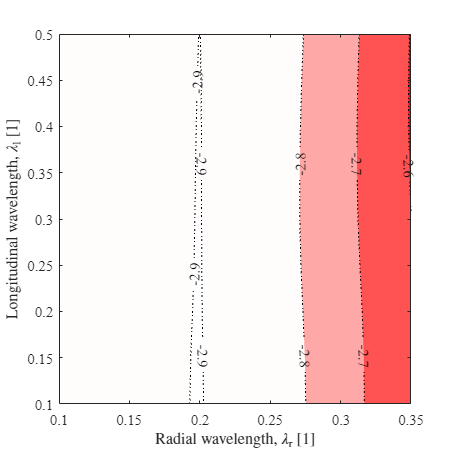

fr_u = symfun(u,[f l(2) A(2)]);
fr_u_num = matlabFunction(fr_u);
% freq = 10e3*logspace(0,1,1601);
freq = [10e3 50e3 75e3];

% C-21 material properties for logitudinal dimension
pld.E33 = 6.4e10;
pld.rho	= 7800;
pld.c3	= sqrt(pld.E33/pld.rho);
pld.f0	= 75e3;
pld.lambda3 = pld.c3/pld.f0;

% % C-21 material properties for radial dimension
prd.E11 = 8.3e10;
prd.rho	= 7800;
prd.c1	= sqrt(prd.E11/prd.rho);
prd.f0	= 75e3;
prd.lambda1 = prd.c1/prd.f0;

lRatio = 0.1:0.05:0.5;
rRatio = 0.1:0.05:0.35;

l2 = pld.lambda3*lRatio;
A2 = pi*(prd.lambda1/2*rRatio).^2;

u_num.u = zeros(length(l2), length(A2), 3, length(freq));

u_FEM_temp = import_COMSOL_array('D -230727 - ECM Validation - 2 - l2.txt');
uCount_FEM = int32(length(u_FEM_temp)/(length(l2)*length(A2)));
u_FEM.freq = u_FEM_temp(1:uCount_FEM,3);
u_FEM.u = reshape(u_FEM_temp(:,4),uCount_FEM,length(A2),[]);
u_FEM.u = permute(u_FEM.u,[3 2 1]);

for i=1:length(l2)
    for j=1:length(A2)
        u_num.u(i,j,:,:) = fr_u_num(freq, l2(i), A2(j));
        
        % u75.ECM(i,j) = interp1(freq,squeeze(u_num.u(i,j,2,:)),pld.f0);
        % u75.FEM(i,j) = interp1(freq,squeeze(u_num.u(i,j,:)),pld.f0);
    end
end

err.r10 = abs((squeeze(u_num.u(:,:,1,1))-u_FEM.u(:,:,1))./u_FEM.u(:,:,1));
err.r50 = abs((squeeze(u_num.u(:,:,1,2))-u_FEM.u(:,:,2))./u_FEM.u(:,:,2));
err.r75 = abs((squeeze(u_num.u(:,:,1,3))-u_FEM.u(:,:,3))./u_FEM.u(:,:,3));

[X, Y] = meshgrid(rRatio, lRatio);
% contourf(X, Y, abs(squeeze(u_num.u(:,:,1,:))));
% contourf(X, Y, abs(u_FEM.u));
createfigure_contour(X,Y,log10(err.r10),0.1)

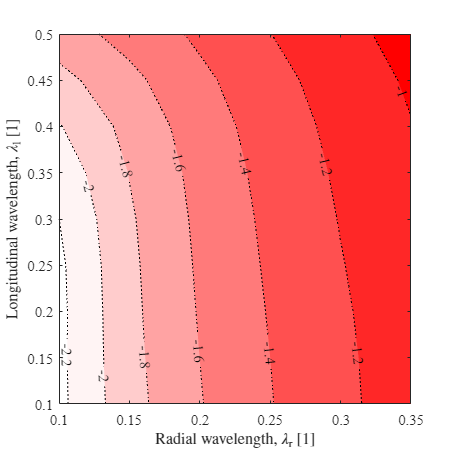

createfigure_contour(X, Y, log10(err.r50),0.2);

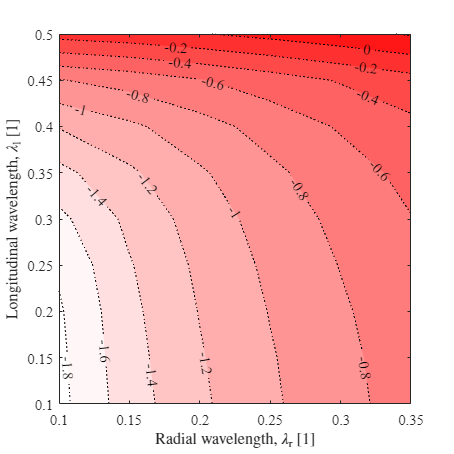

createfigure_contour(X, Y, log10(err.r75),0.2);

freq = 10e3:100:100e3;
u_num = fr_u_num(freq,4e-3,pi*7e-3^2);
% createfigure_fr(freq, abs(u_num(2,:))',"u_3","Frequency [Hz]","Velocity [m/s] and Current [A]","log","log")
% fplot(abs(fr_u(f)),[50e3 100e3])


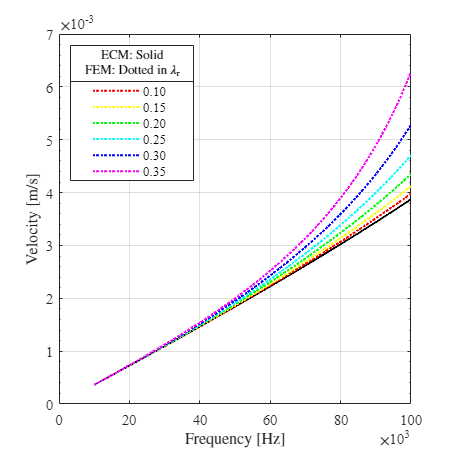

u_FEM = import_COMSOL_array('D -230727 - ECM Validation - 2.txt');
uCount_FEM = int32(length(u_FEM)/6);
u_FEM_freq = u_FEM(1:uCount_FEM,2);
u_FEM = reshape(u_FEM(:,3),uCount_FEM,[]);

createfigure_fr_comp2(freq, abs(u_num(2,:))',u_FEM_freq,abs(u_FEM), ...
    "northwest", ...
    {"ECM: Solid", "FEM: Dotted in $\lambda_\mathrm{r}$"},"ECM",["0.10" "0.15" "0.20" "0.25" "0.30" "0.35"], ...
    "Frequency $\left[\mathrm{Hz}\right]$","Velocity $\left[\mathrm{m/s}\right]$","linear","linear")

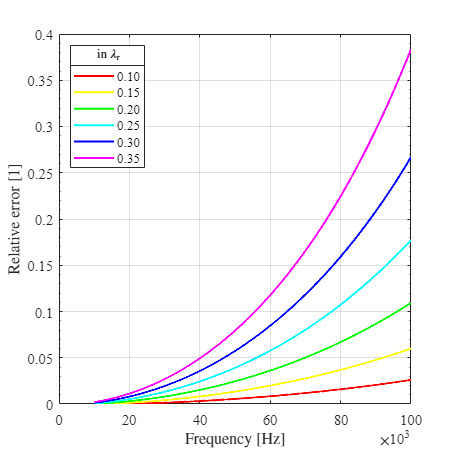

u_FEM_interp1 = interp1(u_FEM_freq, u_FEM, freq);
uError = (repmat(u_num(2,:)',1,6)-u_FEM_interp1)./u_FEM_interp1;

createfigure_fr2(freq, abs(uError), ...
    "northwest", ...
    "in $\lambda_\mathrm{r}$",["0.10" "0.15" "0.20" "0.25" "0.30" "0.35"], ...
    "Frequency $\left[\mathrm{Hz}\right]$","Relative error [1]","linear","linear")

% u_FEM_Avg = import_COMSOL_array('D -230727 - ECM Validation - 2 Avg.txt');
% uCount_FEM = int32(length(u_FEM_Avg)/6);
% u_FEM_Avg_freq = u_FEM_Avg(1:uCount_FEM,2);
% u_FEM_Avg = reshape(u_FEM_Avg(:,3),uCount_FEM,[]);
% 
% createfigure_fr_comp2(freq, abs(u_num(2,:))',u_FEM_Avg_freq,abs(u_FEM_Avg), ...
%     "","ECM",["0.10\lambda" "0.15\lambda" "0.20\lambda" "0.25\lambda" "0.30\lambda" "0.35\lambda"], ...
%     "Frequency [Hz]","Velocity [m/s]","linear","linear")
% 
% u_FEM_Avg_interp1 = interp1(u_FEM_Avg_freq, u_FEM_Avg, freq);
% uError = (repmat(u_num(2,:)',1,6)-u_FEM_Avg_interp1)./u_FEM_Avg_interp1;
% 
% createfigure_fr(freq, abs(uError),["0.10\lambda" "0.15\lambda" "0.20\lambda" "0.25\lambda" "0.30\lambda" "0.35\lambda"],"Frequency [Hz]","Relative error [1]","linear","linear")

% % u5_OBS     = import_COMSOL('D -230725 - OBS rework by WJ w.o. Plate.txt');
% % 
% % createfigure_fr_comp(freq, abs(u_num(5,:))', u5_OBS.freq, u5_OBS.v5, '', "u_5", ...
% %     'Frequency [Hz]','Velocity [m/s]','linear','log')